clear;clc;close all;
%global m X_added_mass X_lin_damp X_quad_damp ref;
global m X_added_mass X_quad_damp ref;
m = 40415;
X_added_mass = -3375;
%X_lin_damp = -86;
X_quad_damp = -8.36;
ref = 5;
x0 = 0;
tspan = [0 5000];
[t,x] = ode45(@(t,x) sistema(t,x),tspan,x0);

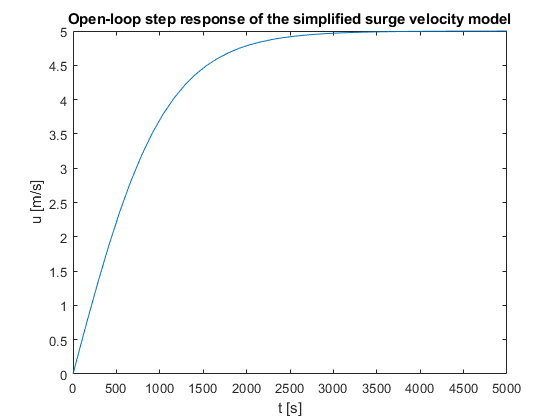

plot(t,x)
title('Open-loop step response of the simplified surge velocity model')
xlabel('t [s]')
ylabel('u [m/s]')
saveas(gcf,'degrau_surge_MA.png')


stepinfo = stepinfo(x,t,ref)

stepinfo = struct with fields:
        RiseTime: 1.4371e+03
    SettlingTime: 2.4072e+03
     SettlingMin: 4.5999
     SettlingMax: 4.9993
       Overshoot: 0
      Undershoot: 0
            Peak: 4.9993
        PeakTime: 5000


ts = stepinfo.SettlingTime

ts = 2.4072e+03

function xponto = sistema(t,x)
    global m X_added_mass X_quad_damp ref;
    u = -X_quad_damp*ref*abs(ref); % u => tau (entrada)
    xponto = (u+X_quad_damp*x*abs(x))/(m-X_added_mass); % xponto => uponto (estado e saida)
    
end